# Nonlinear Simulation of QT System

clear
clc
clf
rng default

% Parameters
p.R = 4;                                % cm, tank radius
p.A = pi*p.R^2;                         % cm^2, tank area
p.r = 0.345/2;                              % cm, hole radius
% p.a = pi*p.r^2;                         % cm^2, hole area
p.a = [pi*p.r^2, pi*p.r^2, pi*p.r^2, pi*p.r^2];
% p.gamma1 = 0.4;                         % ~, valve coefficient
% p.gamma2 = 0.4;                         % ~, valve coefficient
% p.gamma3 = 0.6;
% p.gamma4 = 0.6;
p.g = 981;                              % cm/s^2, acceleration due to gravity

% % External Variables
% u.v1 = @(t) 5;     % V, pump voltage
% u.v2 = @(t) 4;      % V, pump voltage



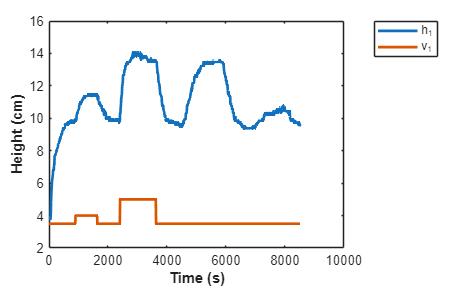

% Load Step Data
steps = 100;
data = load("steps_run2.mat");
time = data.steps.get("eTape1").Values.Time(1:steps:end);

% eTape 1 & Pump 1
h1 = data.steps.get("eTape1").Values.Data(1:steps:end);
v1 = data.steps.get("v1").Values.Data(1:steps:end);

figure(1);
plot(time, h1, "LineWidth", 2)
hold on
plot(time, v1, "LineWidth", 2)
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
legend("h_1", "v_1", "Location", "bestoutside")
hold off

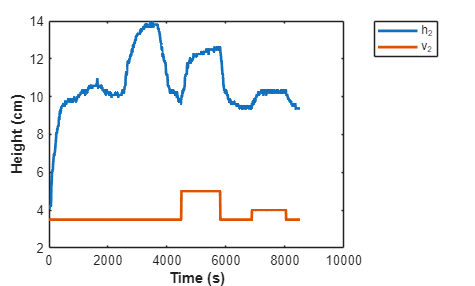


% eTape 2 & Pump 2
h2 = data.steps.get("eTape2").Values.Data(1:steps:end);
v2 = data.steps.get("v2").Values.Data(1:steps:end);

figure(2);
plot(time, h2, "LineWidth", 2)
hold on
plot(time, v2, "LineWidth", 2)
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
legend("h_2", "v_2", "Location", "bestoutside")
hold off


% vector of measured heights and voltages
h_meas = [h1, h2];
v_meas = [v1, v2];

% % bounds on beta
% beta0 = [1, 1, 0.4, 0.4];
% lb = [0, 0, 0, 0];
% ub = [5, 5, 1, 1];

% External Variables
u.v1 = @(t) interp1(time, v_meas(:, 1), t, "nearest", "extrap");
u.v2 = @(t) interp1(time, v_meas(:, 2), t, "nearest", "extrap");

% Solving Unknown Parameters
% beta0 = [1.2, 1.2, 1.8, 1.8, 0.0935, 0.0935, 0.0935, 0.0935];
% beta0 = [1.2, 1.2, 1.8, 1.8];
% beta0 = [1.9, 1.7, 1.7, 1.9];

% bounds on beta
% lb = ones(1, length(beta0))*1e-3;
% ub = [5, 5, 5, 5];
% options = optimoptions("lsqnonlin", "Display", "iter");

% beta_fit = lsqnonlin(@(beta) obj_func(beta, time, h_meas, u, p), beta0, lb, ub, options)
% [3.4763, 3.5347, 0.3882, 0.4539] @ [3.3, 3.3, 0.4, 0.4]
% [3.2997, 3.7151, 0.3385, 0.4199] @ [3.3, 3.3, 0.3, 0.3]
% [2.9789, 4.0150, 0.3172, 0.4223] @ [1, 1, 0.4, 0.4]

% interior point
% [1.9888, 1.5196, 1.6283, 2.0529]

% trust-region
% [1.8469, 1.7323, 1.7841, 1.8495]

% levenberg-maquardt
% [2.0483, 1.8296, 1.6334, 1.7842]

% multistart
% problem = createOptimProblem("lsqnonlin", "objective", @(beta) obj_func(beta, time, h_meas, u, p), "x0", beta0, "lb", lb, "ub", ub, "options", options);
% ms = MultiStart;
% ms.MaxTime = 1800;
% tic
% beta_fit = run(ms, problem, 20)
% toc

% updating parameters
% parameters to be determined
beta_fit = [1.8651, 1.7397, 1.7650, 1.8425]

beta_fit =     1.8651    1.7397    1.7650    1.8425


p.c1 = beta_fit(1);           
p.c2 = beta_fit(2);          
p.c3 = beta_fit(3);       
p.c4 = beta_fit(4);       
% p.a = [beta_fit(5), beta_fit(6), beta_fit(7), beta_fit(8)];
% beta_fit = [1.8651, 1.7397, 1.7650, 1.8425] <---- values after 20
% MultiStarts

% Solving ODE function
h0 = [h_meas(1, 1); h_meas(1, 2); h_meas(1, 2); h_meas(1, 1)];
[t_final, h_final] = ode45(@(t, h) ODE(t, h, u, p), time, h0);

% compute the mean absolute percentage error (MAPE)
MAPE_1 = mape(h_final(:, 1), h1)

MAPE_1 = 6.2405

MAPE_2 = mape(h_final(:, 2), h2)

MAPE_2 = 6.9799

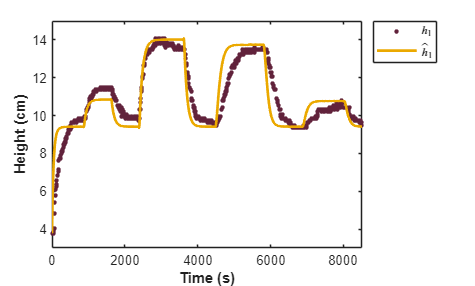


figure(3);
plot(time, h1, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t_final, h_final(:, 1), "LineWidth", 2, "Color", "#eba900")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
legend({"$h_1$", "$\hat{h}_1$"}, "Interpreter", "latex", "Location", "bestoutside")
xlim([0 time(end)])
ylim([3 15])
hold off

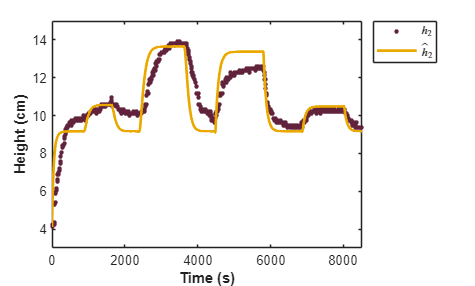


figure(4)
plot(time, h2, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t_final, h_final(:, 2), "LineWidth", 2, "Color", "#eba900")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
legend({"$h_2$", "$\hat{h}_2$"}, "Interpreter", "latex", "Location", "bestoutside")
xlim([0 time(end)])
ylim([3 15])
hold off

## Transfer Function Matrix

% v_ss = 4 V (find corresponding time values for when each pump is at 4 V)
h1_ss = h_final(time == 1290, 1)

h1_ss = 10.8399

h2_ss = h_final(time == 7490, 2)

h2_ss = 10.4836

h3_ss = h_final(time == 7490, 3)

h3_ss = 2.9062

h4_ss = h_final(time == 1290, 4)

h4_ss = 3.1681

tau1 = (p.A*sqrt(2*p.g*h1_ss))/(p.a(1)*p.g)

tau1 = 79.9345

tau2 = (p.A*sqrt(2*p.g*h2_ss))/(p.a(2)*p.g)

tau2 = 78.6100

tau3 = (p.A*sqrt(2*p.g*h3_ss))/(p.a(3)*p.g)

tau3 = 41.3889

tau4 = (p.A*sqrt(2*p.g*h4_ss))/(p.a(4)*p.g)

tau4 = 43.2136

c1 = sqrt(2*p.g*h1_ss)/(p.a(1)*p.g)

c1 = 1.5902

c2 = sqrt(2*p.g*h2_ss)/(p.a(2)*p.g)

c2 = 1.5639


% putting the transfer functions together
s = tf("s");
G11 = (c1*beta_fit(1))/(tau1*s + 1)


G11 =
 
     2.966
  -----------
  79.93 s + 1
 
Continuous-time transfer function.


G12 = (c1*beta_fit(3))/((tau1*s + 1)*(tau3*s + 1))


G12 =
 
          2.807
  ----------------------
  3308 s^2 + 121.3 s + 1
 
Continuous-time transfer function.


G21 = (c2*beta_fit(4))/((tau2*s + 1)*(tau4*s + 1))


G21 =
 
          2.881
  ----------------------
  3397 s^2 + 121.8 s + 1
 
Continuous-time transfer function.


G22 = (c1*beta_fit(2))/(tau2*s + 1)


G22 =
 
     2.767
  -----------
  78.61 s + 1
 
Continuous-time transfer function.



% gain matrix
K = [c1*beta_fit(1), c1*beta_fit(3); c2*beta_fit(4), c1*beta_fit(2)]

K =     2.9660    2.8068
    2.8815    2.7666


det_K = det(K)

det_K = 0.1178

## Comparing Models

% residual ODE function
function res = obj_func(beta, time, h_meas, u, p)
    % parameters to be determined
    p.c1 = beta(1);           
    p.c2 = beta(2);           
    p.c3 = beta(3);
    p.c4 = beta(4);
    % p.a = [beta(5), beta(6), beta(7), beta(8)];

    % solving ODE
    h0_res = [h_meas(1, 1); h_meas(1, 2); h_meas(1, 1); h_meas(1, 2)];
    [~, h_res] = ode45(@(t, h) ODE(t, h, u, p), time, h0_res);

    % residuals
    res = h_res(:, [1, 2]) - h_meas;
    res = res(:);
end
    % ODE function
function dhdt = ODE(t, h, u, p)
    dhdt = zeros(4, 1);
    dhdt(1) = (u.v1(t).*p.c1 + p.a(3).*sqrt(2.*p.g.*h(3)) - p.a(1).*sqrt(2.*p.g.*h(1)))./p.A;
    dhdt(2) = (u.v2(t).*p.c2 + p.a(4).*sqrt(2.*p.g.*h(4)) - p.a(2).*sqrt(2.*p.g.*h(2)))./p.A;
    dhdt(3) = (u.v2(t).*p.c3 - p.a(3).*sqrt(2.*p.g.*h(3)))./p.A;
    dhdt(4) = (u.v1(t).*p.c4 - p.a(4).*sqrt(2.*p.g.*h(4)))./p.A;
end